# ModSim Project 1 - SIR Model

*Authors:* Lili Baker, Olivia Chang, Tyler Ewald

*Our Learning Objectives:* As a result of writing this notebook, we (the authors) hope to:

- **Work on real world models: **Gain experience modeling the real world and learn to test model on “real world” data. Better understand how to structure and choose a type of model for real world scenario.

- **Interpretation and iteration: **Learn how to analyze a model and improve upon it; get better at interpreting and explaining model data

- **Coding Best Practices:** Improve code commenting to help debug and ensure others can understand code 

### Modeling Question

What public health interventions are most likely to be effective in reducing total number of infections in an SIR model of the flu? We will consider interventions aimed at changing the infection rate, the recovery rate, rate, or the rate at which people become able to be re-infected.

## 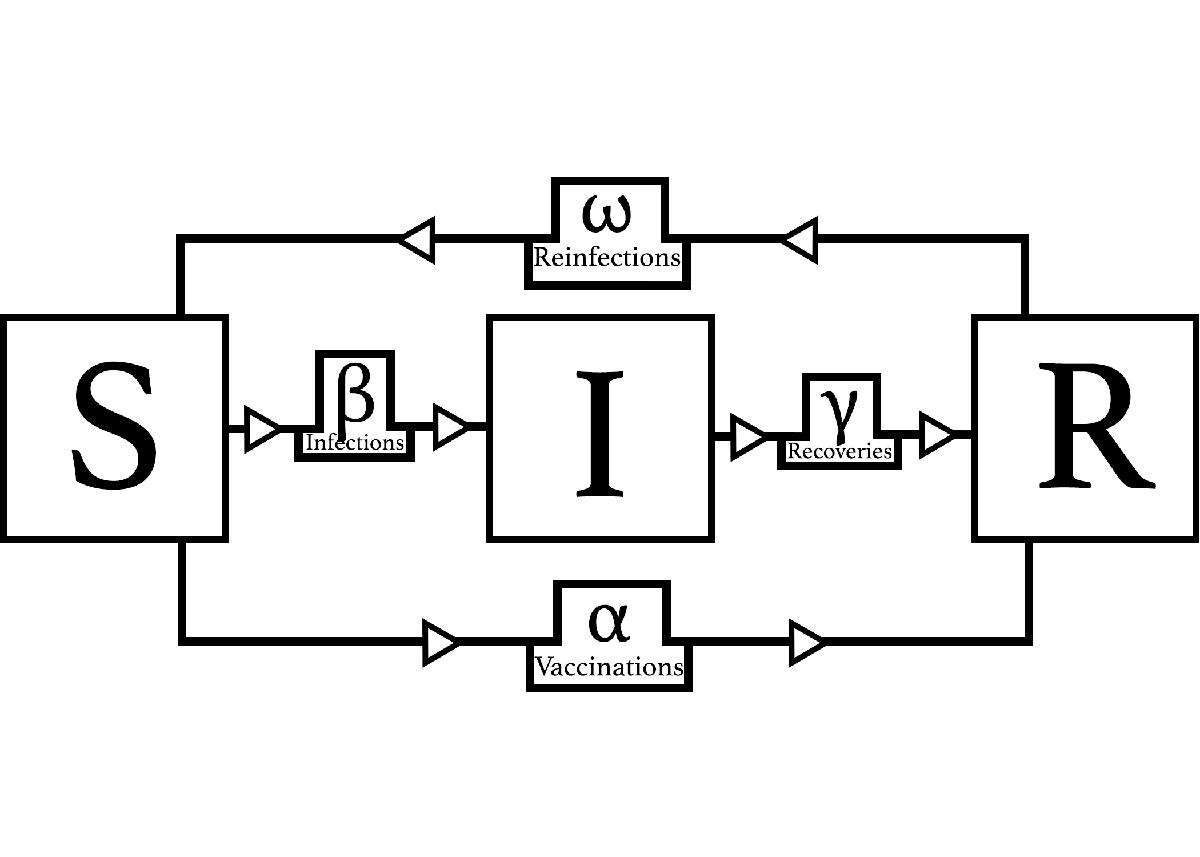

## Model Parameters

The following are the parameters of the model:

- **beta:** infectivity of disease

- **gamma **is determined by the length of recovery period

- **alpha **is determined by the community rate of vaccination

- **omega **is determined by how long it takes to lose immunity

## How to Calculate and Interpret Model Results

**What does total mean? **Total infections is the number of distinct individual flu cases. if someone is infected twice (in the first flu season, then the second) then their situation will be counted as two cases.

## Global Variables

These are variables that don't change from simulation to simulation! We've defined them as global here because we want to be able to access them across multiple functions.

Note: for every function that needs these variables, the first line of code `global num_steps i_0 s_0 r_0;` must be added in the top.

global num_steps i_0 s_0 r_0;
num_steps = 104;
i_0 = 2;       % Initial count of infected persons
s_0 = 100 - i_0;
r_0 = 0;

## Model Baseline

The following model is our baseline, against which each additonal simulation will be compared. This baseline:

- **Excludes vaccinations:** no one is vaccinated in this scenario

- **Lost immunity: **Assumes everyone loses immunity after 52 weeks of recovery

- **Time span: **Runs over the course of 104 weeks, or 2 years (steps).

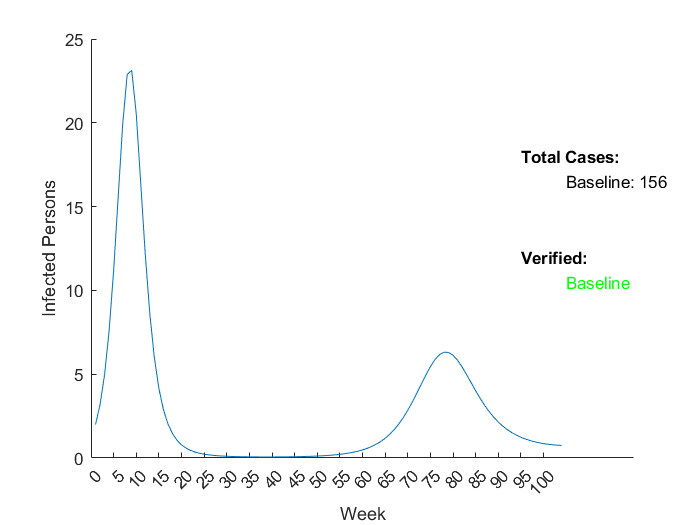

ans = 155.9205

plot_baseline()

**Interpretation:** As we can see from the chart, this model shows two times in which the number of infected persons peaks—thus flu seasons—over the course of two years. The second flu season has a smaller peak than the first, showing that the second flu season is less severe than the first.

## Part 1: Interventions Which Affect The Flow From Susceptible to Recovered

The intervention studied that affected the flow from susceptible to recovered is vaccinations. Vaccinations confer immunity to a given disease, allowing persons to move from the susceptible to recovered stock without passing through the infected stock. Thus, we study the ability of vaccinating given percentages of the population to reduce the number of cases.

In this model, we assume that a vaccine is developed for each flu season, and that there are enough doses available for each person to be vaccinated in each flu season if they so choose. Thus, given that there are two flu seasons and 100 persons in the population, the maximum possible of shots administered is 200 shots. Here, we model a population in which approximately 50% of the population is vaccinated, and 100% of the population is vaccinated.

## 2.5% Vaccination Model

- Assumes 2.5% of the total population is being vaccinated each week.

- This results in 100 shots administered over the two flu seasons, which is 50% of the 200 possible.

- This is a realistic scenario which tracks closely with the current nationwide vaccination rate of 51.8% (Kaiser Family Foundation).

- Assumes immunity is lost after a period of time.

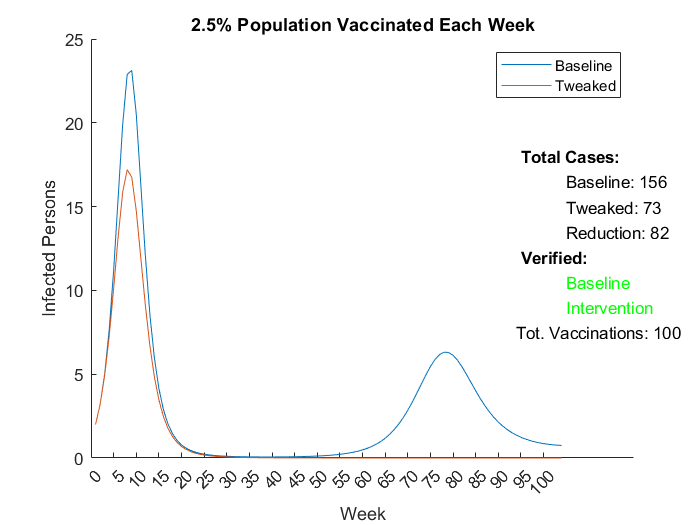

simulation_name = "2.5% Population Vaccinated Each Week";
I_total_baseline = plot_baseline();

% Define flow parameters
beta = 1 / 90;
gamma = 1 / 2;
alpha = 0.025;
omega = 1 / 52;

plot_intervention(beta, gamma, alpha, omega, I_total_baseline, simulation_name)

**Interpretation:** If a public health campaign were executed in which 2.5% of the community was vaccinated per week, the number of cases would drop significantly, and prevent the emergence of a second flu season entirely.

## 9.25% Vaccination Model

- Assumes 9.25% of the total population is being vaccinated each week.

- This results in 200 shots administered over the two flu seasons, which is 100% of the 200 possible.

- Generally, this is an unrealistic scenario as it is unlikely for the entirely population in most scenarios to be vaccinated. However, this is an important scenario to consider as it is an aspirational scenario for many public health experts.

- Assumes immunity is lost after a period of time.

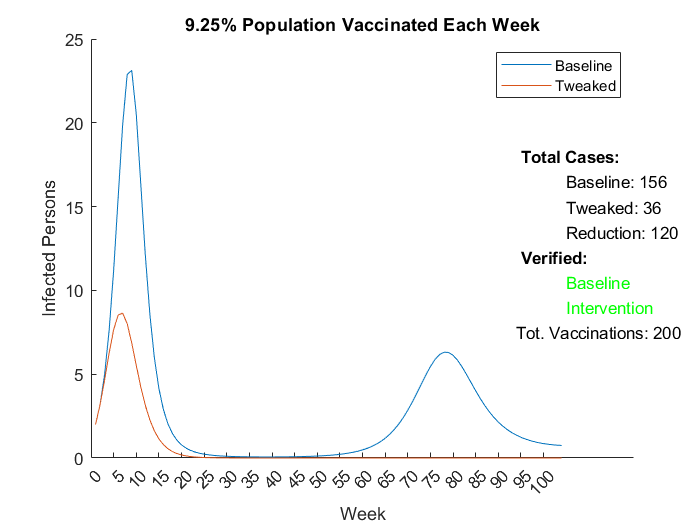

simulation_name = "9.25% Population Vaccinated Each Week";
I_total_baseline = plot_baseline();

beta = 1 / 90;
gamma = 1 / 2;
alpha = 0.0925;
omega = 1 / 52;

plot_intervention(beta, gamma, alpha, omega, I_total_baseline, simulation_name)

**Interpretation: **If a public health campaign were executed in which 9% of the community was vaccinated per week, the number of cases would drop significantly, and prevent the emergence of a second flu season entirely. However, while the reduction is significantly more than the baseline, it is not significantly more than the 2.5% vaccination model, which is easier to implement from a public health perspective. As such, it is unnecessary to vaccinate the entire population.

## Part 2: Interventions Which Affect The Flow From Infected to Recovered

The intervention studied that reduce the flow from infected to recoverd is the use of antiviral drugs. According to Lehnert, "the efficacy of antiviral drugs ranges from 60% to 90%... depending on the population and type of drug in question" (Lehnert). Consequently, antiviral drugs reduce the length of infection by approximately 0.5 to 1.5 days for patients that are infected by the flu with a typical infectious time of seven days (Lehnert). Given that this model assumes the typical infectious time to be fourteen days, the effect of antiviral drugs was doubled, resulting in a reduction of infectious time with a range of 1 to 3 days.

## Reduce Infectious Time By 1 Day

- No vaccinations

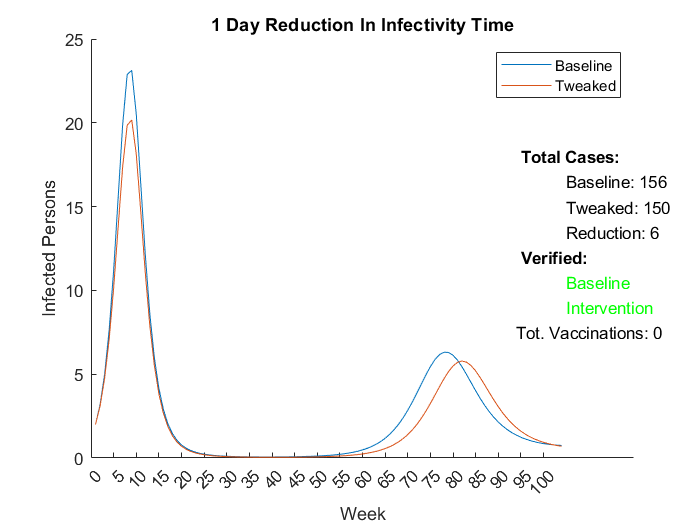

simulation_name = "1 Day Reduction In Infectivity Time";
I_total_baseline = plot_baseline();

reduction_infectious_time = 1;
infected_time = (2*7 - reduction_infectious_time) / 7;
beta = 1 / 90;
gamma = 1 / infected_time;
alpha = 0;
omega = 1 / 52;

plot_intervention(beta, gamma, alpha, omega, I_total_baseline, simulation_name)

**Interpretation:** If the infected population was treated with antiviral drugs that reduced the duration of infection by one day, the number of cases would decrease by six cases, and the second wave would occur later.

## Reduce Infectious Time By 2 Days

- No vaccinations

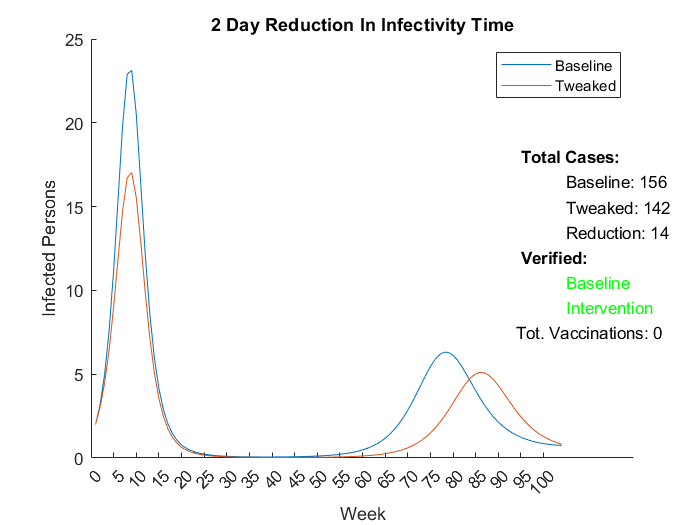

simulation_name = "2 Day Reduction In Infectivity Time";
I_total_baseline = plot_baseline();

reduction_infectious_time = 2;
infected_time = (2*7 - reduction_infectious_time) / 7;
beta = 1 / 90;
gamma = 1 / infected_time;
alpha = 0;
omega = 1 / 52;

plot_intervention(beta, gamma, alpha, omega, I_total_baseline, simulation_name)

**Interpretation:** If the infected population was treated with antiviral drugs that reduced the duration of infection by two days, the number of cases would decrease by 14 cases, and the second wave would occur much later.

## Reduce Infectious Time By 3 Days

- No vaccinations

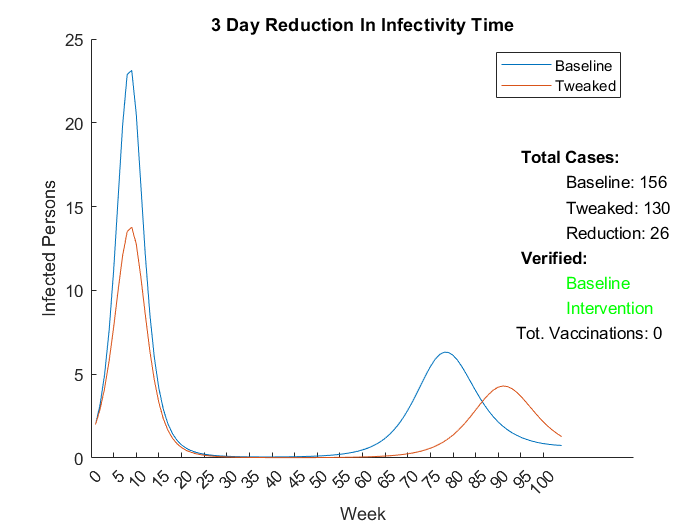

simulation_name = "3 Day Reduction In Infectivity Time";
I_total_baseline = plot_baseline();

reduction_infectious_time = 3;
infected_time = (2*7 - reduction_infectious_time) / 7;
beta = 1 / 90;
gamma = 1 / infected_time;
alpha = 0;
omega = 1 / 52;

plot_intervention(beta, gamma, alpha, omega, I_total_baseline, simulation_name)

**Interpretation:** If the infected population was treated with antiviral drugs that reduced the duration of infection by three days, the number of cases would decrease by 26 cases, and the second wave would occur much later.

## Part 3: Interventions Which Affect The Flow From Susceptible to Infected

The interventions implemented in this model that affect the flow from susceptible to infected consist of home confinement with a 50% compliance rate and the closure of schools for three weeks. According to Paleshi, home confinement with a 50% compliance rate reduced the attack rate (beta) by 39.6%, while school closures for three weeks reduced beta by 13.9% (Paleshi).

## Home Confinement with 50% Compliance Rate

- Assumes 50% of the population is staying home.

- No vaccinations.

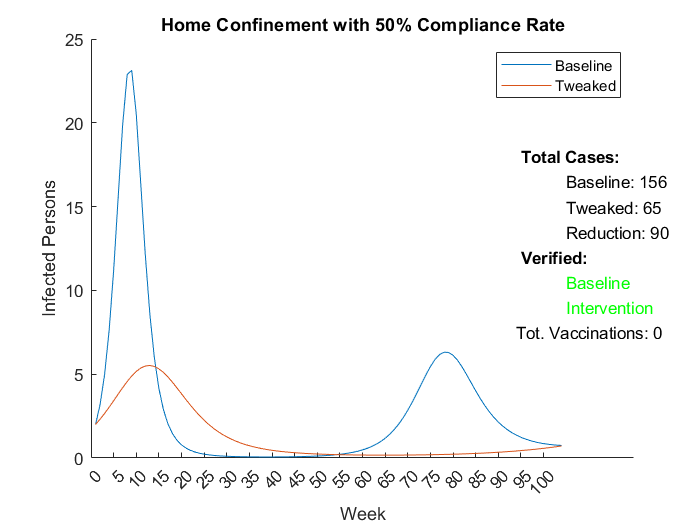

simulation_name = "Home Confinement with 50% Compliance Rate";
I_total_baseline = plot_baseline();

decreaseInAttack = 0.604;
beta = (1 / 90) * decreaseInAttack;
gamma = 1 / 2;
alpha = 0;
omega = 1 / 52;

plot_intervention(beta, gamma, alpha, omega, I_total_baseline, simulation_name)

**Interpretation:** If 50% of the population stayed home, the number of cases would decrease significantly, and the second wave would be almost entirely avoided.

## School Closures for Three Weeks

- Assumes schools are closed for three weeks.

- No vaccinations.

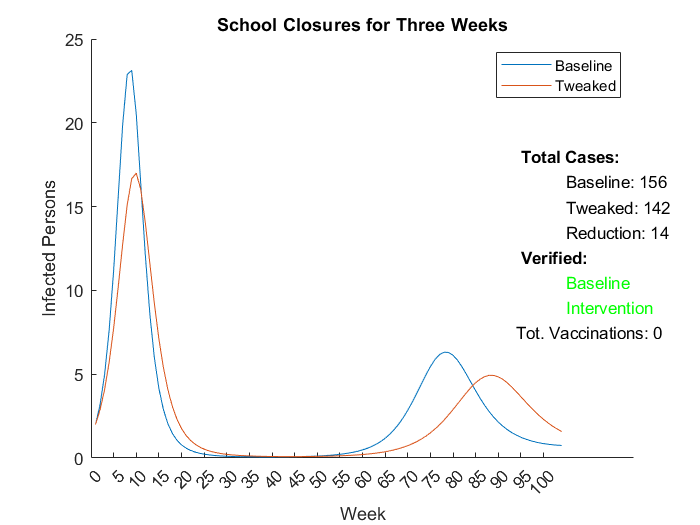

simulation_name = "School Closures for Three Weeks";
I_total_baseline = plot_baseline();

decreaseInAttack = 0.861;
beta = (1 / 90) * decreaseInAttack;
gamma = 1 / 2;
alpha = 0;
omega = 1 / 52;

plot_intervention(beta, gamma, alpha, omega, I_total_baseline, simulation_name)

**Interpretation:** If schools were closed for three weeks, the number of cases would decrease by 14 cases, and the second wave would occur later with fewer case numbers.

## Interpretation:

There are several resources available to public health departments to ease the effects of infections such as the flu. However, each of these steps takes time and resources so finding the most effective one is crucial to stopping a disease without spending unnecessary resources and implementing nonessential closures. Throughout this model, we looked at 3 different Public Health Interventions that each affected a different flow in the SIR model. It is clear that the most effective way to stop the spread is through mass vaccinations to the public. So, if vaccination is available it is by far the most effective method to substantially reducing the impact of the disease. However, vaccines aren't always available to the public, and therefore can't be the only response to an epidemic. The next most effective intervention was damping the flow from susceptible to infected. So, in the event where vaccines aren't available or aren't effective enough, this is a promising route for public health departments to take. With that said, not every type of this intervention is useful. With home confinement, the reduction in case numbers was 90 where it was only 14 in school closures. Once again though, this isn't always an option for public health departments. Due to the destructive nature of these interventions, the public may have major objections to these measures even when facing an incredibly deadly disease. If there is no vaccine and containment strategies aren't an option, the only route to take is disease treatment. Although the least effective out of the option tested, this one is the most reliable. In instances of highly effective treatment (infection time reduced by 3 days), it was able to decrease the case count by 26 or about 17%. In summary, it is clear what is most effective. However, public health departments need to have numerous ways of combating diseases as many of the most effective options aren't always available or realistic to implement. 

## Verification

We utilized 2 different types of verification in our model. The first verification was an overall population verification in which we verified that the total number of people in the simulation never increases or decreases.  The second verification is to ensure that the flow diagrams stay in check. To verify the flows from susceptible, we ensure that the number of people vaccinated and infected in each step never exceeds the number of susceptible people. To verify the recovery flow, we ensure that the number of people moving from infected to recovered never exceeds the number of infected. Finally, to verify the reinfection flow, we check that the number of people moving to susceptible never exceeds the number of people recovered. If the population changes or if any of the flow conditions are violated the program automatically corrects this and changes the verify indicator on the graph to red. 

## Validation

Although we will not be validating our model, it is important to consider hypothetical ways in which we could validate our data. In order to validate our vaccination model, we would pull data from previous flu seasons that experienced different vaccination rates. With this data, we could see whether or not our model accurately demonstrates how differences in vaccination rates affect flu infections. To validate our medical interventions, we would start by pulling data from a recent year and a year before modern disease treatment techniques. We would compare the old data to the baseline and the new data to the adjusted model and this would validate the accuracy of the model predictions. Finally, to validate the model's alpha flow disruptions, we would compare data from during the COVID pandemic (when social distancing and school closures were common) and previous years. Once again we would compare the older data to the baseline, and the COVID year data to the adjusted model.

## Sources

Lehnert, Regine et al. “Antiviral Medications in Seasonal and Pandemic Influenza.” *Deutsches Arzteblatt international* vol. 113,47 (2016): 799-807. doi:10.3238/arztebl.2016.0799

Paleshi, A. et al, "Simulation of mitigation strategies for a pandemic influenza," *Proceedings of the 2011 Winter Simulation Conference (WSC)*, 2011, pp. 1340-1348, doi: 10.1109/WSC.2011.6147855. 